close all;
clear;
clc;

opts = detectImportOptions('/MATLAB Drive/html/PM final project/Running data.csv');
opts.VariableNamingRule = 'preserve';
prc = readtable('Running data.csv',opts);
opts = detectImportOptions('/MATLAB Drive/html/PM final project/MKRT- RF.csv');
opts.VariableNamingRule = 'preserve';
sprf = readtable('/MATLAB Drive/html/PM final project/MKRT- RF.csv',opts);
opts = detectImportOptions('/MATLAB Drive/html/PM final project/Cost-final.csv');
opts.VariableNamingRule = 'preserve';
cost = readtable('/MATLAB Drive/html/PM final project/Cost-final.csv',opts);

%Timestamps (1 DF lost)
dates = datetime(prc.Date(2:end));
% Names of risky assets
alist = prc.Properties.VariableNames(2:end);
% Risky asset prices
aprc = prc(:,alist).Variables;
%Compute risky asset returns
artn = tick2ret(aprc);
% S&P 500 returns (1 DF lost)
brtn = sprf.SPRTRN(2:end);
% Risk free rate (in %, 1 DF lost)
rf = sprf.RF(2:end)/100;
%trading cost
acost = cost(:,alist).Variables;
%Assume 252 working days in a year
rw = 252;
ertn = artn-brtn;

%Calculate each individual asset betas
[m,n]=size(artn);
X=[ones(size(brtn)) brtn-rf];
for i=1:n
    y=artn(:,i)-rf;
    [b,bint,res] = regress(y,X);
    betas(i)=b(2);
end
rbs=7;
for k = 1:length(rbs)
rb = rbs(k);
tp = floor((length(dates)-rw)/rb);
bc = acost./aprc;
ie = 100;

%% Use a rolling window of 252 trading days to estimate the Sharpe ratio optimised portfolio, benchmarked by s&p500.
gcp
parfor i = 1:tp
    rwmean =  mean(rf((i-1)*rb+1:rw+(i-1)*rb));
    rwertn = ertn((i-1)*rb+1:rw+(i-1)*rb,:);
    rwbc = mean(bc((i-1)*rb+1:rw+(i-1)*rb,:))/rb;
    p = Portfolio('AssetList', alist, 'RiskFreeRate',rwmean/252);
    p = setDefaultConstraints(p); % 0<=w<=1
    ep = estimateAssetMoments(p,rwertn,'missingdata',false);
    ep = setInitPort(ep, 1/ep.NumAssets);
    ep = setCosts(ep,rwbc,rwbc);
    maxsharpe(:,i) = estimateMaxSharpeRatio(ep);
end

%% Use the identified max sharpe ratio portfolios to identify the portfolio performance
for i = 1:tp
    rbrtn(i,:) = aprc(rw+ i*rb,:)./ aprc(rw+(i-1)*rb,:)-1;
    acosts(i,:) = acost(rw+ i*rb,:)./aprc(rw+(i-1)*rb,:);
    bbrtn(i,:) = prod(brtn(rw+(i-1)*rb:rw+ i*rb,1)+1)-1;
    rftn(i,:) = prod(rf(rw+(i-1)*rb:rw+ i*rb,1)+1)-1;
    ebbrtn(i,:) = prod(brtn(rw+(i-1)*rb:rw+ i*rb,1)-rf(rw+(i-1)*rb:rw+ i*rb,1)+1)-1;
end

%%
% adjustments cost
    rbcosts(1,:) = dot(maxsharpe(:,1),transpose(acosts(1,:)));
for i = 2:tp
    rbcosts(i,:) = dot(maxsharpe(:,i)-maxsharpe(:,i-1),transpose(acosts(i,:)));
end
% return - costs
pret = transpose(dot(transpose(rbrtn),maxsharpe))-rbcosts;
pval = zeros(tp+1,1);
pval(1,1)= ie;
spx = zeros(tp+1,1);
spx(1,1) = ie;
rfn = zeros(tp+1,1);
rfn(1,1) = ie;
espx = zeros(tp+1,1);
espx(1,1) = ie;
for i = 2:tp+1
    pval(i,1) = (1+pret(i-1,1))*pval(i-1,1);
    spx(i,1) = (1+bbrtn(i-1,1))*spx(i-1,1);
    rfn(i,1) = (1+rftn(i-1,1))*rfn(i-1,1);
    espx(i,1) = (1+ebbrtn(i-1,1))*espx(i-1,1);
end
excess(k)=pval(tp+1);

jen(1)=0;
for i=2:tp
    beta=transpose(maxsharpe(:,i))*transpose(betas); % beta for the max sharpe portfolio
    jen(i)=(pval(i)/pval(i-1)-1)-((rfn(i)/rfn(i-1)-1)-beta*(espx(i)/espx(i-1)-1));
end
r=jen+1;
rc=cumprod(r);
cum_jen=rc-1;
cum_jens(k)=cum_jen(tp);
end


ans = 

  0×0 Pool array with no properties.



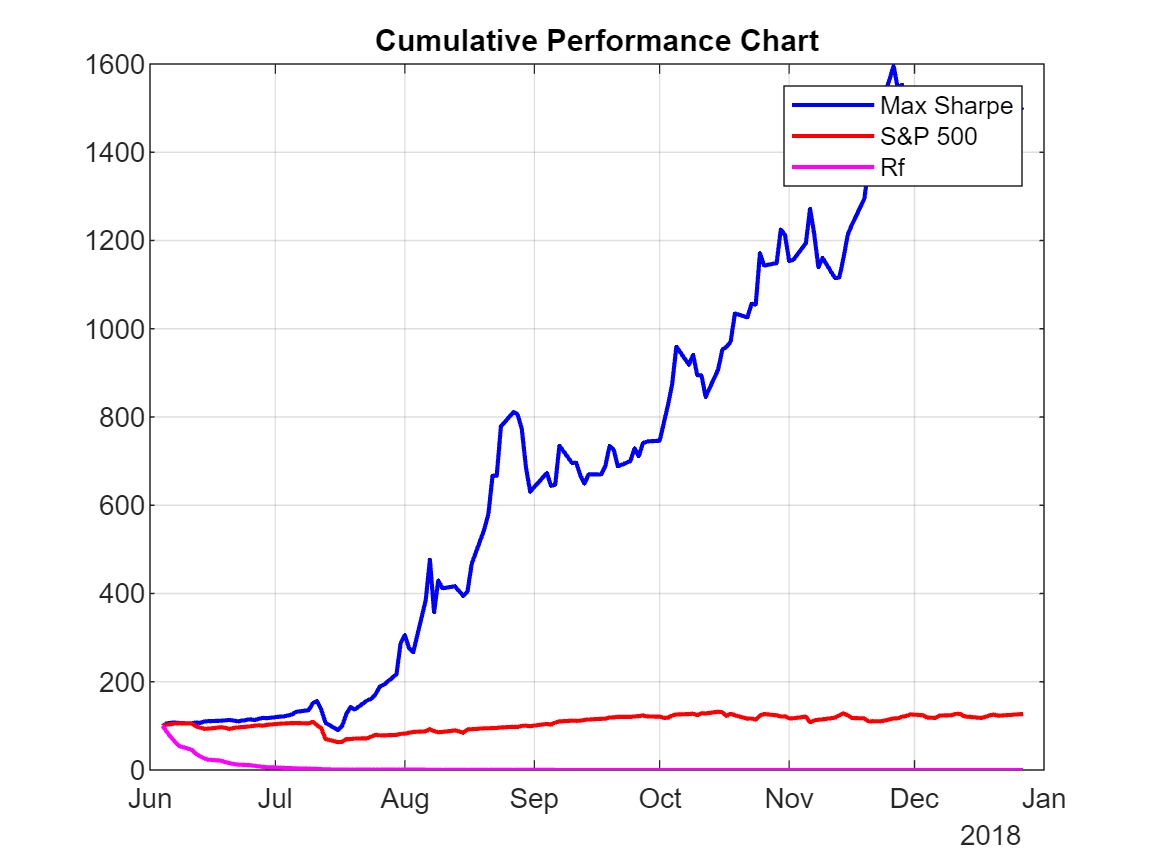

figure;
plot(dates(1:tp+1), pval, 'b-', 'LineWidth', 1.5);
hold on;
plot(dates(1:tp+1), spx, 'r-', 'LineWidth', 1.5);
plot(dates(1:tp+1), espx, 'm-', 'LineWidth', 1.5);
title('Cumulative Performance Chart');
legend('Max Sharpe', 'S&P 500', 'Rf');
grid on;
hold off;

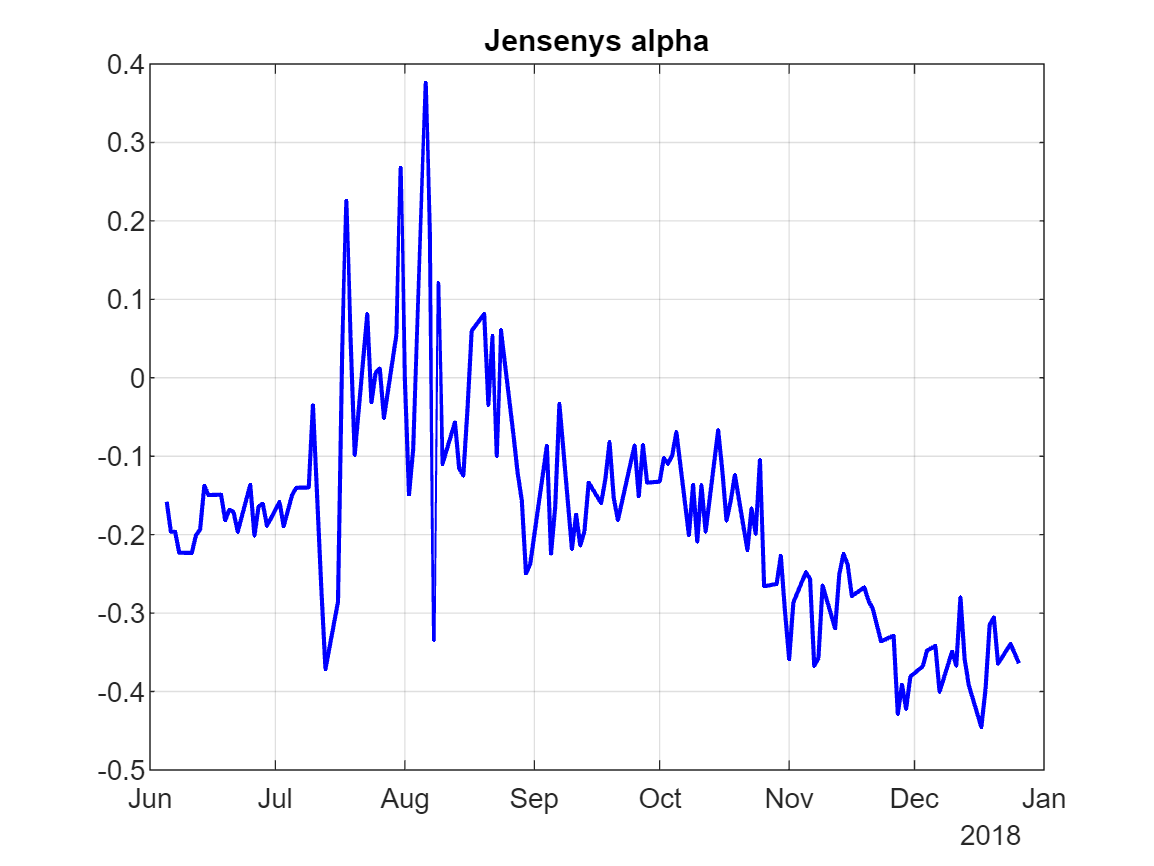

figure;
plot(dates(2:tp), jen(2:tp), 'b-', 'LineWidth', 1.5);
title('Jensenys alpha');
grid on;